# Metoda strumieniowa


clear,clc,close all

k=25;
h0=1000;
T0inf=1700;
hi=200;
Tiinf=400;

dx=0.25;
dy=0.25;
x=0:dx:5;
y=0:dy:3;
max_x=max(x);
max_y=max(y);

a=1*(2+h0*dx/(1000*k))

a = 2.0100

b=2*(2+h0*dx/(1000*k))

b = 4.0200

c=2*(3+hi*dx/(1000*k))

c = 6.0040

d=2*(2+hi*dx/(1000*k))

d = 4.0040

e=1*(hi*dx/(1000*k)+2)

e = 2.0020

f=1*h0*dx/(1000*k)*T0inf

f = 17

g=1*hi*dx/(1000*k)*Tiinf

g = 0.8000


for i=1:length(y)
    for j=1:length(x)
        if x(j)> 2 & y(i)>2
            A(i,j)={[]};
        else
            A(i,j)={[y(i) x(j) [4] [NaN] [NaN] [NaN] [NaN] [NaN]
                [NaN] [NaN] [NaN] [NaN] [NaN] [NaN] ]};
        end
    end
end
tot_el=sum(sum(~cellfun(@isempty,A),2))

tot_el = 225

%%%  neighbours values mapping ( internal corner exception == 5)
for i=1:length(y)
    for j=1:length(x)
        if (y(i)>0 & y(i)<3 & (x(j)==max_x ...
            | x(j)==0) & isempty(A{i,j})==0) 
            | (x(j)>0 & x(j)<5 & (y(i)==0 | y(i)==max_y)& isempty(A{i,j})==0)
            A{i,j}(3)=3;
        elseif x(j)==2 & y(i)==2 & isempty(A{i,j})==0
            A{i,j}(3)=5;
        elseif (x(j)==2 & y(i)>2 & y(i)<3) | (y(i)==2 & x(j)>2 & x(j)<5)
            A{i,j}(3)=3;
        end
        if (x(j)==0 & y(i)==0) |(x(j)==0 & y(i)==max_y) 
            |(x(j)==2 & y(i)==max_y) 
            |(x(j)==max_x & y(i)==2) |(x(j)==max_x & y(i)==0)
            A{i,j}(3)=2;
        end
    end
end
%%% diagonal mappin
for i=1:length(y)
    for j=1:length(x)
        %% upperside
        if isempty(A{i,j})==0 & A{i,j}(2)>0 & A{i,j}(2)<=2 & A{i,j}(1)==0
            A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-b 1 1 2 NaN NaN 0 -2*f 4*dx*h0 0  ];
        elseif isempty(A{i,j})==0 & A{i,j}(2)>2 & A{i,j}(2)<max_x & A{i,j}(1)==0
            A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-b 1 1 2 NaN 0 0 -2*f 4*dx*h0 0 ];
        end
        %% downside
        if isempty(A{i,j})==0 & A{i,j}(2)>0 & A{i,j}(2)<2 & A{i,j}(1)==max_y
            A{i,j}([4 5 6 7 8 9 10 11])=[-4 1 1 NaN 0 2 NaN 0 ];
        end
        %leftside
        if isempty(A{i,j})==0 & A{i,j}(3)==3 & A{i,j}(2)==0
            if A{i,j}(1)>0 & A{i,j}(1)<2+dy
                A{i,j}([4 5 6 7 8 9 10 11])=[-4 2 0 1 1 0 0 0];
            elseif A{i,j}(1)>0 & A{i,j}(1)==2+dy
                A{i,j}([4 5 6 7 8 9 10 11])=[-4 2 0 0 1 0 1 0];
            elseif A{i,j}(1)>2+dy
                A{i,j}([4 5 6 7 8 9 10 11])=[-4 2 0 0 0 1 1 0];
            end
        end
        %%%rightside
        if isempty(A{i,j})==0 & A{i,j}(3)==3 & A{i,j}(2)==max_x
            A{i,j}([4 5 6 7 8 9 10 11])=[-4 0 2 1 1 0 0 0];
        end
        %%% x>2 y=2 x<6
        if isempty(A{i,j})==0 & A{i,j}(3)==3 & A{i,j}(1)==2 
            & A{i,j}(2)>2 & A{i,j}(2)<max_x
            A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-d 1 1 NaN 2 0 0 -2*g 0 4*dx*hi];
        end
        %%% x=2
        if isempty(A{i,j})==0 & A{i,j}(2)==2
            if A{i,j}(1)==2+dx % zmianka
                A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-d 0 2 0 1 0 1 -2*g 0 4*hi*dy];
            elseif A{i,j}(1)>2+dx & A{i,j}(1)<3
                A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-d 0 2 0 0 1 1 -2*g 0 4*hi*dy];
            end
        end
        %% internal
        if isempty(A{i,j})==0 & A{i,j}(3)==4
            if A{i,j}(1)<2+dx
                A{i,j}([4 5 6 7 8 9 10 11])=[-4 1 1 1 1 0 0 0];
            elseif A{i,j}(1)==2+dx
                A{i,j}([4 5 6 7 8 9 10 11])=[-4 1 1 0 1 0 1 0];
            elseif A{i,j}(1)>2+dx & A{i,j}(1)<3
                A{i,j}([4 5 6 7 8 9 10 11])=[-4 1 1 0 0 1 1 0];
            end
        end
        %% corners
        if isempty(A{i,j})==0
            if A{i,j}(1)==0 & A{i,j}(2)==0
                A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-a 1 NaN 1 NaN NaN 0 -f 2*dx*h0 0];
            elseif A{i,j}(1)==max_y & A{i,j}(2)==0
                A{i,j}([4 5 6 7 8 9 10 11])=[-2 1 0 NaN 0 1 NaN 0];
            elseif A{i,j}(1)==max_y & A{i,j}(2)==2
                A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-e NaN 1 NaN 0 1 NaN -g 0 2*dy*hi];
            elseif A{i,j}(3)==5
                A{i,j}([4 5 6 7 8 9 10 11 12 13 ])=[-c 1 2 1 2 0 0 -2*g 0 2*dy*hi+2*dx*hi];
            elseif A{i,j}(1)==2 & A{i,j}(2)==max_x
                A{i,j}([4 5 6 7 8 9 10 11 12 13 ])=[-e 0 1 NaN 1 0 0 -g 0 2*dx*hi];
            elseif A{i,j}(1)==0 & A{i,j}(2)==max_x
                A{i,j}([4 5 6 7 8 9 10 11 12 13])=[-a 0 1 1 NaN 0 0 -f 2*dx*h0 0 ];
            end
        end
    end
end

%% DIAGS
dm=[];d1=[];d_1=[];d7=[];d_7=[];bc=[];d5=[];d_5=[];
for i=1:length(y)
    for j=1:length(x)
        if isempty(A{i,j})==0
            dm(length(dm)+1)=A{i,j}(4);
            d1(length(d1)+1)=A{i,j}(5);
            d_1(length(d_1)+1)=A{i,j}(6);
            d7(length(d7)+1)=A{i,j}(7);
            d_7(length(d_7)+1)=A{i,j}(8);
            d5(length(d5)+1)=A{i,j}(10);
            d_5(length(d_5)+1)=A{i,j}(9);
            bc(length(bc)+1,1)=A{i,j}(11);
        end
    end
end
%%
d1 = d1(~isnan(d1));
d_1 = d_1(~isnan(d_1));
d7 = d7(~isnan(d7));
d_7 = d_7(~isnan(d_7));
d5 = d5(~isnan(d5));
d_5 = d_5(~isnan(d_5));
%% matrix
B=zeros(tot_el)+diag(dm)+diag(d1,1)+diag(d_1,-1)

B =    -2.0100    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000   -4.0200    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    2.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

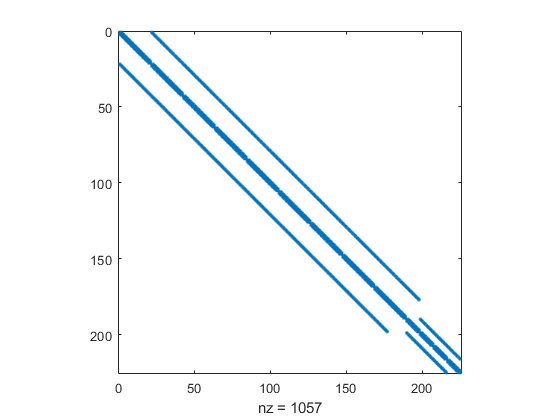

+diag(d7,length(x))+diag(d_7,-length(x))
+diag(d5,length(dm)-length(d5))+diag(d_5,-(length(dm)-length(d5)))
spy(B)

%% solver
T=inv(B)*bc

T = 	1.0e+03 *

    1.5259
    1.5258
    1.5257
    1.5255
    1.5252
    1.5249
    1.5245
    1.5241
    1.5237
    1.5233


o=1;
in=1;
out=1;
qin=[];
qout=[];
for i=1:length(y)
    for j=1:length(x)
        if isempty(A{i,j})==0
            A{i,j}(14)=T(o);
            o=o+1;
            %qin
            if isempty(A{i,j}(12))==0
                A{i,j}(12)=A{i,j}(12)*(T0inf-A{i,j}(14));
                qin(length(qin)+in)=A{i,j}(12);
            end
            if isempty(A{i,j}(13))==0
                A{i,j}(13)=A{i,j}(13)*(A{i,j}(14)-Tiinf);
                qout(length(qout)+out)=A{i,j}(13);
            end
        end
    end
end
qin = 4*sum(qin(~isnan(qin)));
qout = 4*sum(qout(~isnan(qout)));
qabs=qin-qout;
error_qin=abs(qabs/qin*100);
error_qout=abs(qabs/qout*100);
error_rel=(error_qin+error_qout)/2;
header={'x';'y';'T'};
o=1;
%% scope
for i=1:length(y)
    for j=1:length(x)
        if isempty(A{i,j})==0
            Z(i,j)={A{i,j}([12 13])};
            x_final(o,1)=A{i,j}(2);
            y_final(o,1)=A{i,j}(1);
            T_final(o,1)=A{i,j}(14);
            o=o+1;
        end
    end
end
t=table([x_final],[y_final],[T_final])

t = 225×3 table
    x_final    y_final    T_final
    _______    _______    _______

        0         0       1525.9 
     0.25         0       1525.8 
      0.5         0       1525.7 
     0.75         0       1525.5 
        1         0       1525.2 
     1.25         0       1524.9 
      1.5         0       1524.5 
     1.75         0       1524.1 
        2         0       1523.7 
     2.25         0       1523.3 
      2.5         0       1522.8 
     2.75         0       1522.4 
        3         0         1522 
     3.25         0       1521.7 
      3.5         0       1521.4 
     3.75         0       1521.1 


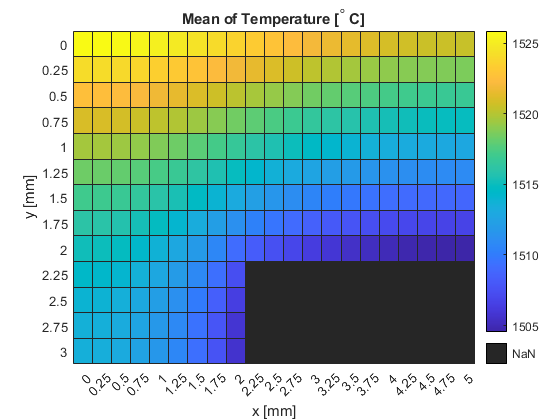

h =   HeatmapChart (Mean of Temperature [^{\circ} C]) with properties:

      SourceTable: [225×3 table]
        XVariable: 'x [mm]'
        YVariable: 'y [mm]'
    ColorVariable: 'Temperature [^{\circ} C]'
      ColorMethod: 'mean'

  Show all properties


t = renamevars(t,["x_final","y_final","T_final"], ...
    ["x [mm]","y [mm]","Temperature [^{\circ} C]"]);
h = heatmap(t,'x [mm]','y [mm]','ColorVariable', ...

    'Temperature [^{\circ} C]','Colormap',parula)
for i=1:length(y)
    for j=1:length(x)
        if isempty(A{i,j})==0
            Z(i,j)={A{i,j}([12 13])};
            x_final(o,1)=10-A{i,j}(2);
            y_final(o,1)=A{i,j}(1);
            T_final(o,1)=A{i,j}(14);
            o=o+1;
        end
    end
end
for i=1:length(y)
    for j=1:length(x)
        if isempty(A{i,j})==0
            Z(i,j)={A{i,j}([12 13])};
            x_final(o,1)=10-A{i,j}(2);
            y_final(o,1)=6-A{i,j}(1);
            T_final(o,1)=A{i,j}(14);
            o=o+1;
        end
    end
end
for i=1:length(y)
    for j=1:length(x)
        if isempty(A{i,j})==0
            Z(i,j)={A{i,j}([12 13])};
            x_final(o,1)=A{i,j}(2);
            y_final(o,1)=6-A{i,j}(1);
            T_final(o,1)=A{i,j}(14);
            o=o+1;
        end
    end
end
t=table([x_final],[y_final],[T_final])

t = 900×3 table
    x_final    y_final    T_final
    _______    _______    _______

        0         0       1525.9 
     0.25         0       1525.8 
      0.5         0       1525.7 
     0.75         0       1525.5 
        1         0       1525.2 
     1.25         0       1524.9 
      1.5         0       1524.5 
     1.75         0       1524.1 
        2         0       1523.7 
     2.25         0       1523.3 
      2.5         0       1522.8 
     2.75         0       1522.4 
        3         0         1522 
     3.25         0       1521.7 
      3.5         0       1521.4 
     3.75         0       1521.1 


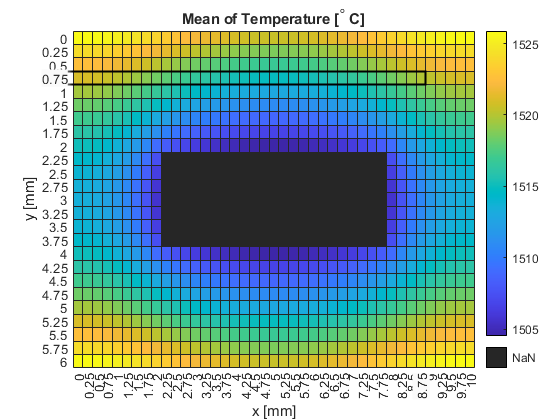

h =   HeatmapChart (Mean of Temperature [^{\circ} C]) with properties:

      SourceTable: [900×3 table]
        XVariable: 'x [mm]'
        YVariable: 'y [mm]'
    ColorVariable: 'Temperature [^{\circ} C]'
      ColorMethod: 'mean'

  Show all properties


t = renamevars(t,["x_final","y_final","T_final"], ...
    ["x [mm]","y [mm]","Temperature [^{\circ} C]"]);
h = heatmap(t,'x [mm]','y [mm]','ColorVariable', ...

    'Temperature [^{\circ} C]','Colormap',parula)




